Effectiveness profiling of RSQP from wind tunnel data

ismac = 1;
if ismac
    p = parselog('/Users/tomasodeponti/Desktop/logs_sd_1403/80_01_07__20_22_44_SD.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\19_21_53\19_21_53\22_02_10__19_21_53.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end

ac_data = p.aircrafts.data;

Select filtering criteria

la_x = ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_x - mean(ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_x);
la_y = ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_y - mean(ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_y);
la_z = ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_z - mean(ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_z);

y_x = fft(la_x);
y_y = fft(la_y);
y_z = fft(la_z);

n = length(la_x);          % number of samples
fs = get_sf(ac_data.STAB_ATTITUDE_FULL_INDI.timestamp);
f = (0:n-1)*(fs/n);     % frequency range
power_x = abs(y_x).^2/n;    % power of the DFT
power_y = abs(y_y).^2/n;
power_z = abs(y_z).^2/n;
power   = power_x + power_y + power_z;

figure(101)
subplot(4,1,1)
plot(f,power_x)
xlabel('Frequency')
ylabel('Power')
title('X')

subplot(4,1,2)
plot(f,power_y)
xlabel('Frequency')
ylabel('Power')
title('Y')

subplot(4,1,3)
plot(f,power_z)
xlabel('Frequency')
ylabel('Power')
title('Z')

subplot(4,1,4)
plot(f,power)
xlabel('Frequency')
ylabel('Power')
title('Total')


f_filter = 3.9;

Prepare acceleration signal

%rot_times = wing_rot_finder(ac_data);
t_acc = ac_data.STAB_ATTITUDE_FULL_INDI.timestamp;
p = ac_data.STAB_ATTITUDE_FULL_INDI.angular_rate_p;
q = ac_data.STAB_ATTITUDE_FULL_INDI.angular_rate_q;
r = ac_data.STAB_ATTITUDE_FULL_INDI.angular_rate_r;
sf_acc = get_sf(t_acc);
a_p = low_butter(diff_scaled(p,t_acc),f_filter,sf_acc,0);
a_q = low_butter(diff_scaled(q,t_acc),f_filter,sf_acc,0);
a_r = low_butter(diff_scaled(r,t_acc),f_filter,sf_acc,0);
acc = [a_p,a_q,a_r];

Prepare actuator command signal 0-9600

act_names = {"Motor Front","Motor Right","Motor Back","Motor Left","Aileron Left", "Aileron Right","Elevator","Rudder","Push Motor","Rot Mech"};
t_act = t_acc;%ac_data.ACTUATORS.timestamp;
sf_act = get_sf(t_act);
act = cellfun(@(S) sscanf(S, '%f,').', ac_data.STAB_ATTITUDE_FULL_INDI.u, 'Uniform', 0);
act = cell2mat(act);


act1 = act(:,1);%low_butter(act(:,1),f_filter,sf_act,0);
act2 = act(:,2);%low_butter(act(:,2),f_filter,sf_act,0);
act3 = act(:,3);%low_butter(act(:,3),f_filter,sf_act,0);
act4 = act(:,4);%low_butter(act(:,4),f_filter,sf_act,0);
act5 = act(:,5);%low_butter(act(:,5),f_filter,sf_act,0);
act6 = act(:,6);%low_butter(act(:,6),f_filter,sf_act,0);
act7 = act(:,7);%low_butter(act(:,7),f_filter,sf_act,0);
act8 = act(:,8);%low_butter(act(:,8),f_filter,sf_act,0);

pwm_as = [1100,1900];
pwm_mot = [1000,2000];
pprz_as = [-9600,9600];
pprz_mot = [0,9600];

rate_lim = 12300;

m1 = pwm2pprz(pp_limiter(act1,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, 500, sf_act),pwm_mot,pprz_mot);

A =
 
    0.6321
  ----------
  z - 0.3679
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.6321

beta = 0.3679

m2 = pwm2pprz(pp_limiter(act2,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, 500, sf_act),pwm_mot,pprz_mot);

A =
 
    0.6321
  ----------
  z - 0.3679
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.6321

beta = 0.3679

m3 = pwm2pprz(pp_limiter(act3,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, 500, sf_act),pwm_mot,pprz_mot);

A =
 
    0.6321
  ----------
  z - 0.3679
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.6321

beta = 0.3679

m4 = pwm2pprz(pp_limiter(act4,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, 500, sf_act),pwm_mot,pprz_mot);

A =
 
    0.6321
  ----------
  z - 0.3679
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.6321

beta = 0.3679

as1 = pwm2pprz(pp_limiter(act5,pwm_as(2),pwm_as(1),0,rate_lim/9.6, 500, sf_act),pwm_as,pprz_as);

A =
 
    0.6321
  ----------
  z - 0.3679
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.6321

beta = 0.3679

as2 = pwm2pprz(pp_limiter(act6,pwm_as(2),pwm_as(1),0,rate_lim/9.6, 500, sf_act),pwm_as,pprz_as);

A =
 
    0.6321
  ----------
  z - 0.3679
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.6321

beta = 0.3679

as3 = pwm2pprz(pp_limiter(act7,pwm_as(2),pwm_as(1),0,rate_lim/9.6, 500, sf_act),pwm_as,pprz_as);

A =
 
    0.6321
  ----------
  z - 0.3679
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.6321

beta = 0.3679

as4 = pwm2pprz(pp_limiter(act8,pwm_as(2),pwm_as(1),0,rate_lim/9.6, 500, sf_act),pwm_as,pprz_as);

A =
 
    0.6321
  ----------
  z - 0.3679
 
Sample time: 0.002 seconds
Discrete-time transfer function.



alpha = 0.6321

beta = 0.3679



act_aug = [m1,m2,m3,m4,as1,as2,as3,as4,ones(size(m1))];
% 

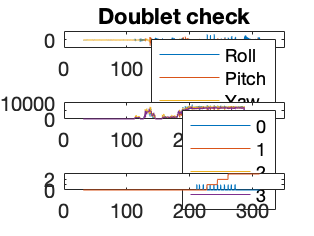

figure(1)
clf
ax1=subplot(3,1,1);
plot(t_acc(2:end),acc)
legend("Roll","Pitch","Yaw")
title('Doublet check')
ax2=subplot(3,1,2);
plot(t_act,act_aug(:,1:4))
legend("0","1","2","3")
ax3=subplot(3,1,3);
plot(ac_data.DOUBLET.timestamp,ac_data.DOUBLET.doublet_active)
hold on
plot(ac_data.DOUBLET.timestamp,ac_data.DOUBLET.doublet_axis)
linkaxes([ax1,ax2,ax3],'x');

Select only timestamps where doublets were performed to estimate the effectiveness of the actuators.

    {["Motor Front"]}



   -0.0003   -0.0033    0.0009
    1.7671   18.3499   -5.2230



    {["Motor Front"]}



    0.0025   -0.0031   -0.0006
  -14.1598   17.8335    3.1587



    {["Motor Right"]}



    0.0012   -0.0010    0.0015
   -8.6530    6.5884  -10.0794



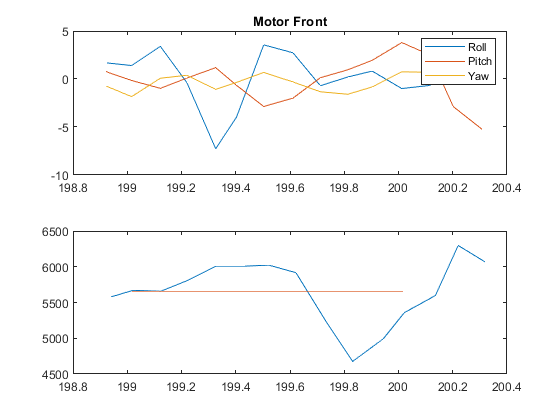

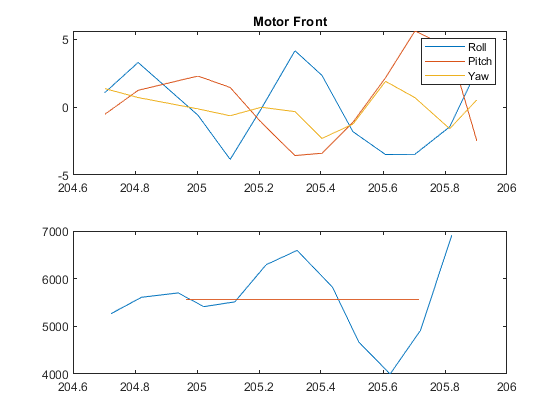

    {["Motor Right"]}



    0.0078   -0.0005    0.0031
  -53.1079    3.2777  -21.4362



    {["Motor Back"]}



    0.0022    0.0026    0.0018
  -17.4441  -20.8773  -14.1654



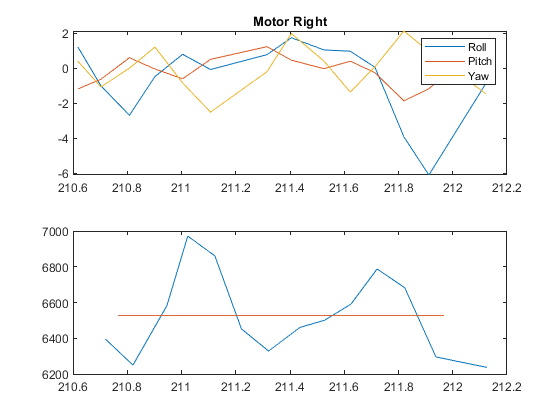

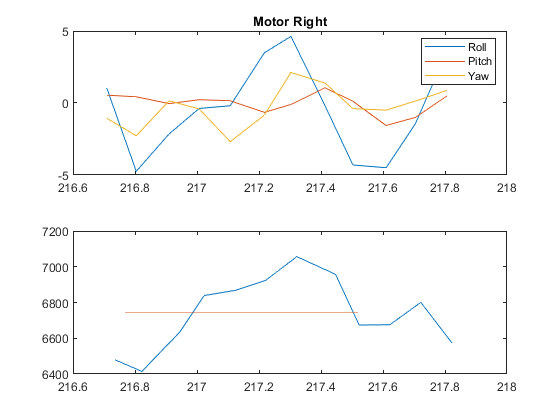

    {["Motor Back"]}



    0.0012    0.0016    0.0014
   -9.1004  -12.3756  -10.8582



    {["Motor Left"]}



   -0.0031   -0.0008   -0.0000
   20.1878    5.2012    0.1077



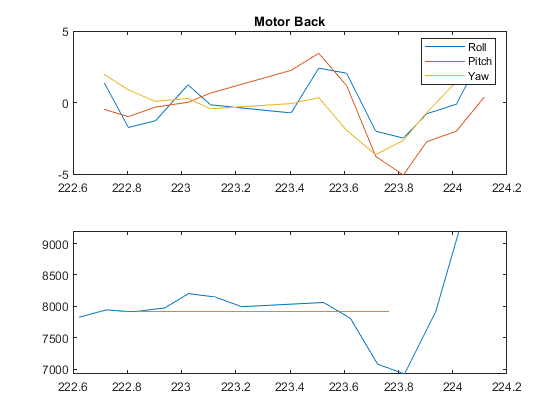

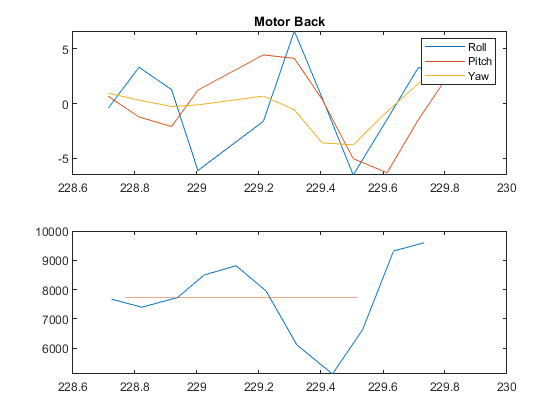

    {["Motor Left"]}



   -0.0024    0.0008   -0.0011
   16.0101   -4.9887    6.7618



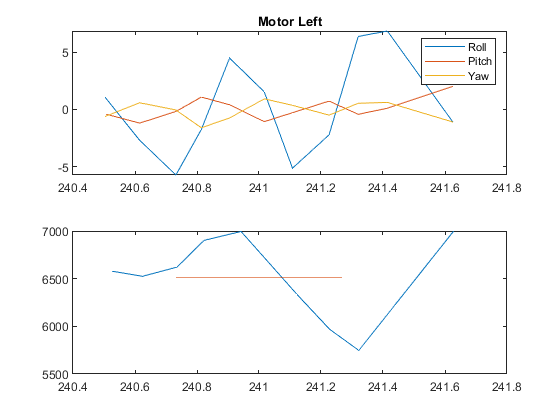

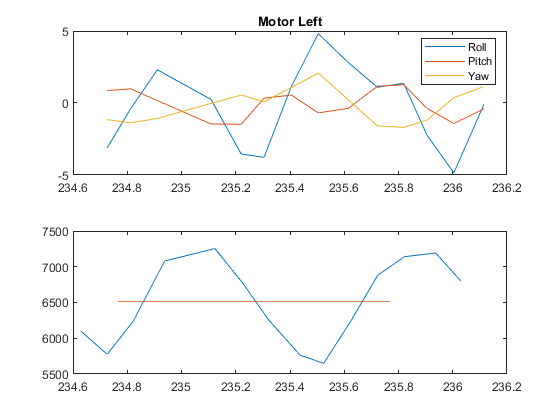

    {["Aileron Left"]}



    0.0011   -0.0003   -0.0001
   -0.2296    0.1151   -0.0452



    {["Aileron Left"]}



    0.0008   -0.0003    0.0002
   -0.0047    0.1455   -0.0252



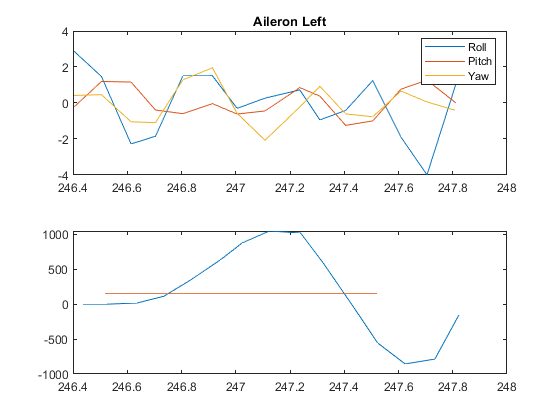

    {["Aileron Right"]}



    0.0006   -0.0004    0.0004
   -0.2334    0.1144    0.0333



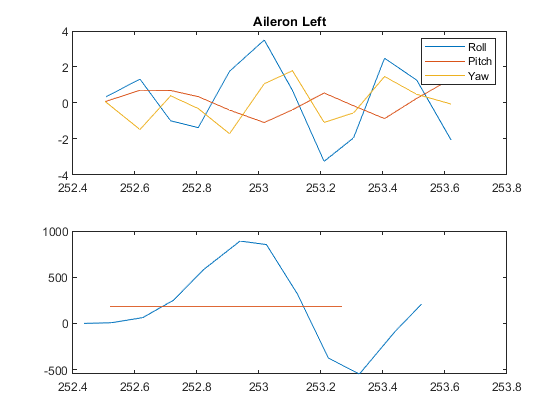

    {["Aileron Right"]}



    0.0015   -0.0002    0.0002
   -0.3342   -0.0572   -0.0228



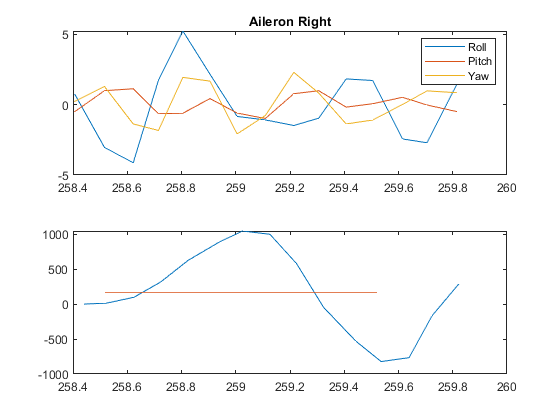

    {["Elevator"]}



   -0.0012   -0.0003    0.0004
   11.4265    3.0560   -4.1108



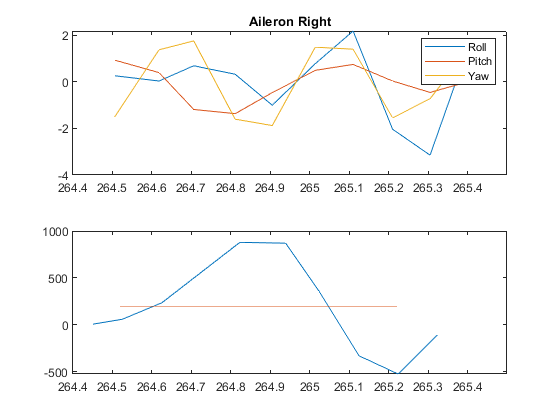

    {["Elevator"]}



    0.0103   -0.0010   -0.0060
  -98.5883    9.9716   57.9343



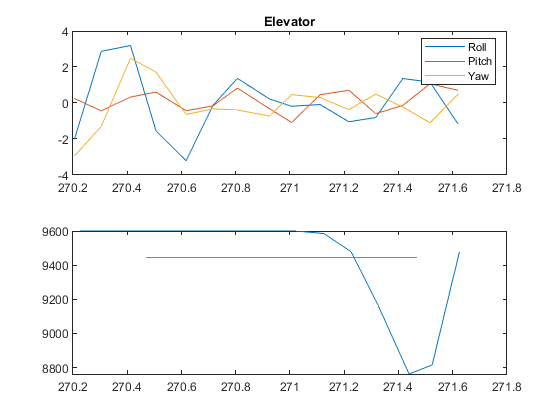

    {["Rudder"]}



   -0.0010    0.0001   -0.0001
    1.4372   -0.3681    0.1857



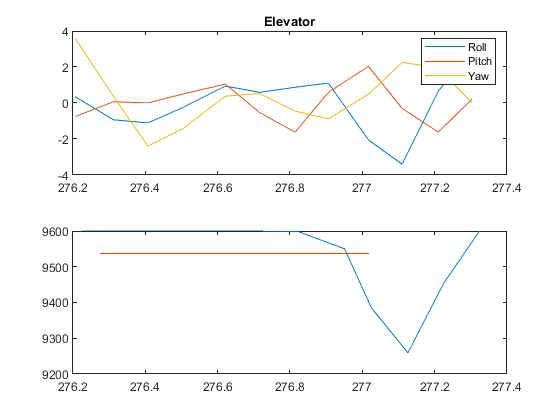

    {["Rudder"]}



   -0.0001    0.0000    0.0002
    0.1791   -0.0375   -0.1913



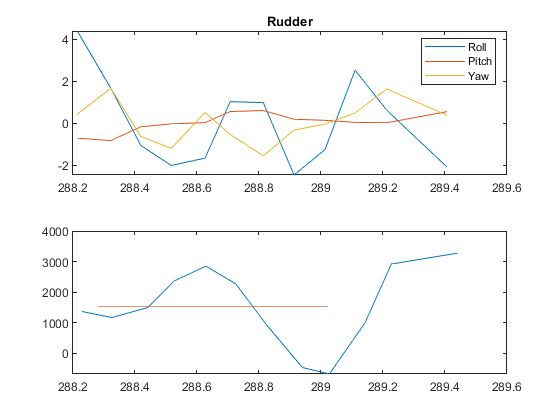

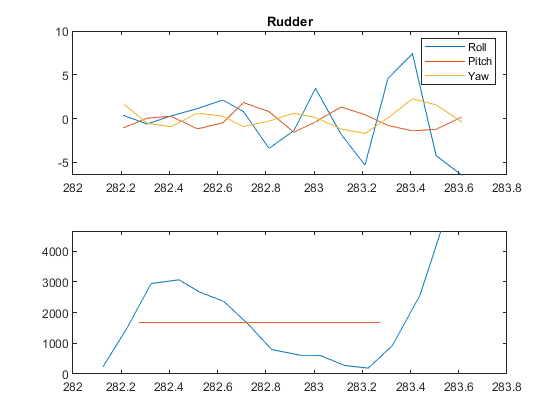

slack_match = 0.1;%0.57;
dou_active = ac_data.DOUBLET.doublet_active;
t_d_active = ac_data.DOUBLET.timestamp(dou_active==1)+slack_match;
t_s = [];
t_e = [];
i_s = [];
i_e = [];
n = size(ac_data.DOUBLET.timestamp,1);
check = 1;
for i=2:n
    a = dou_active(i-1);
    b = dou_active(i);
    if a==0 && b==1
        t_s = [t_s,ac_data.DOUBLET.timestamp(i)+slack_match];
        i_s = [i_s,i+round(slack_match*sf_acc,0)];
    elseif a==1 && b==0
        t_e = [t_e,ac_data.DOUBLET.timestamp(i)+slack_match];
        i_e = [i_e,i+round(slack_match*sf_acc,0)];
        check = check+1;
    end
    if check > 16
        break
    end
end

idx_save_act = [];
idx_save_acc = [];
idx_check = [];
slack = 0.2;
for i=1:size(t_s,2)
    idx_act_s = t_finder(t_act,t_s(i)-slack);
    idx_act_e = t_finder(t_act,t_e(i)+slack);
    
    idx_acc_s = t_finder(t_acc,t_s(i)-slack);
    idx_acc_e = t_finder(t_acc,t_e(i)+slack);

    a = idx_act_e-idx_act_s;
    b = idx_acc_e-idx_acc_s;
    idx_check = [idx_check,[a;b]];
    
    if a > b
        c = a-b;
        idx_act_s = idx_act_s+ mod(c,2)+ fix(c/2);
        idx_act_e = idx_act_e- fix(c/2);
    elseif a < b
        c = b-a;
        idx_acc_s = idx_acc_s+ mod(c,2)+ fix(c/2);
        idx_acc_e = idx_acc_e- fix(c/2);
    end


    idx_save_act = [idx_save_act,idx_act_s:idx_act_e];
    idx_save_acc = [idx_save_acc,idx_acc_s:idx_acc_e];
    n = fix(i/2)+mod(i,2);
    act_aug_d = [act_aug(idx_act_s:idx_act_e,n),act_aug(idx_act_s:idx_act_e,end)];
    acc_d = acc(idx_acc_s:idx_acc_e,:);
    effectiveness_mat = act_aug_d\acc_d;
    disp(act_names(n))
    disp(effectiveness_mat)

    
    figure(i)
    clf
    
    ax1=subplot(2,1,1);
    plot(t_acc(idx_acc_s:idx_acc_e),acc(idx_acc_s:idx_acc_e,:))
    legend("Roll","Pitch","Yaw")
    title(act_names(n))
    ax2=subplot(2,1,2);
    plot(t_act(idx_act_s:idx_act_e),act_aug_d(:,1))
    hold on
    plot(ac_data.DOUBLET.timestamp(i_s(i):i_e(i)),ones(size(i_s(i):i_e(i))).*mean(act_aug_d(:,1)))
    
    linkaxes([ax1,ax2],'x');
    
end

Perform estimation over multiple doublets to reduce bias error


idx_save_acc = idx_save_acc.';%unique(idx_save_acc.','rows');
idx_save_act = idx_save_act.';%unique(idx_save_act.','rows');
act_aug_d = act_aug(idx_save_act,1:end-1);
acc_d = acc(idx_save_acc,:);
effectiveness_mat = act_aug_d\acc_d;
disp(effectiveness_mat*10)

   -0.0007   -0.0013   -0.0026
   -0.0027   -0.0054    0.0049
    0.0030    0.0044    0.0021
   -0.0002    0.0015   -0.0070
    0.0106   -0.0031    0.0003
    0.0087   -0.0036    0.0044
   -0.0004   -0.0001    0.0008
    0.0016    0.0001    0.0013

